Ap = 0.07;
Aa = 50;
Wp1 = 600;
Wp2 = 1000;
Wa1 = 450;
Wa2 = 1100;
Ws = 3000;
T = 2*pi/Ws ;
X = -100:100;
Bt = min([(Wp1-Wa1),(Wa2-Wp2)]);
Wc1 = Wp1 - Bt/2;
Wc2 = Wp2 + Bt/2;

%calculating delta
deltap = (10^(0.05*Ap)-1)/(10^(0.05*Ap)+1) ;
deltaa = 10^-(0.05*Aa) ;
delta = min([deltap,deltaa]);

%calculating actual stopband attenution
Aa1 = -20*log10(delta);
%calculating alpha
if Aa1<= 21
 alpha = 0;
elseif Aa1>50
 alpha = 0.1102*(Aa1-8.7);
else
 alpha = 0.5842*((Aa1-21)^0.4) + 0.07886*(Aa1-21);
end

%calculating value of D
if Aa1<=21
 D= 0.9222;
else
 D = (Aa1-7.95)/14.36;
end

%calculating value of N
if mod(round(1+(Ws*D)/Bt),2)==0
 N = round(1+(Ws*D)/Bt)+1;
else
 N = round(1+(Ws*D)/Bt);
end
lim_N=(N-1)/2;
len_filter=-lim_N:1:lim_N;

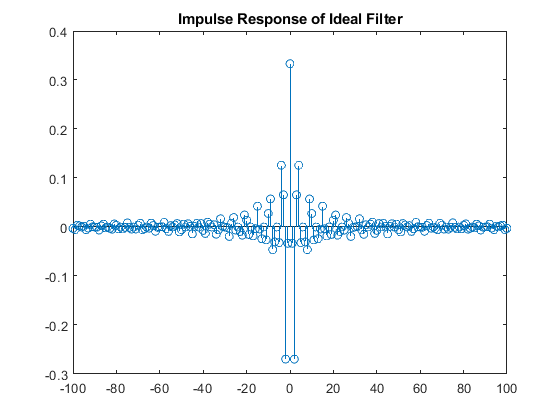

%plotting impulse response
figure
[hnT] = ideal(X,Wc2,Wc1,Ws,T);
stem(X,hnT)
title('Impulse Response of Ideal Filter')

Functions

function [h] = ideal(X,Wc2,Wc1,Ws,T) %function for impulse response
h = zeros(size(X));
    for n = X
        idx = X==n;
        if n == 0
            h(idx) = 2*(Wc2-Wc1)/Ws;
        else
            h(idx) = (1/(n*pi))*(sin(Wc2*n*T)-sin(Wc1*n*T));
        end
    end
end 